# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

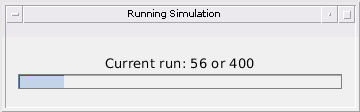

target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   110.7254       NaN       NaN       NaN       NaN
  110.5659       NaN       NaN       NaN       NaN
  110.5014       NaN       NaN       NaN       NaN
  110.4531       NaN       NaN       NaN       NaN
  110.3869       NaN       NaN       NaN       NaN
  110.1606       NaN       NaN       NaN       NaN
  106.8985       NaN       NaN       NaN       NaN
  109.1737       NaN       NaN       NaN       NaN
  110.4211       NaN       NaN       NaN       NaN
  101.1527       NaN       NaN       NaN       NaN


actual_ranges =   110.0000  110.0667  110.1334  110.2000  110.2667  110.3334  110.4001  110.4668  110.5335  110.6001


estimated_velocities =    -1.9891       NaN       NaN       NaN       NaN
   -1.9927       NaN       NaN       NaN       NaN
   -1.9861       NaN       NaN       NaN       NaN
   -1.9891       NaN       NaN       NaN       NaN
   -1.9833       NaN       NaN       NaN       NaN
   -1.9813       NaN       NaN       NaN       NaN
   -2.0212       NaN       NaN       NaN       NaN
   17.1311       NaN       NaN       NaN       NaN
   -1.9568       NaN       NaN       NaN       NaN
  -30.8489       NaN       NaN       NaN       NaN


actual_velocities =     -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected =      1     1     1     1     1     1     1     0     1     0


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges =     0.7254
    0.4992
    0.3680
    0.2530
    0.1201
    0.1728
    3.5016
         0
    0.1124
         0


percent_error_velocities =     0.0109
    0.0073
    0.0139
    0.0109
    0.0167
    0.0187
    0.0212
         0
    0.0432
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   130.9001       NaN       NaN       NaN       NaN
  128.4058       NaN       NaN       NaN       NaN
  128.1690       NaN       NaN       NaN       NaN
  128.2965       NaN       NaN       NaN       NaN
  128.6407       NaN       NaN       NaN       NaN
  130.3708       NaN       NaN       NaN       NaN
  129.6865       NaN       NaN       NaN       NaN
  129.0483       NaN       NaN       NaN       NaN
  130.3019       NaN       NaN       NaN       NaN
  130.6440       NaN       NaN       NaN       NaN


actual_ranges =   130.0000  129.8666  129.7333  129.5999  129.4665  129.3332  129.1998  129.0664  128.9331  128.7997


estimated_velocities =     4.0210       NaN       NaN       NaN       NaN
    3.9823       NaN       NaN       NaN       NaN
    4.0005       NaN       NaN       NaN       NaN
    4.0130       NaN       NaN       NaN       NaN
    4.0182       NaN       NaN       NaN       NaN
    3.9739       NaN       NaN       NaN       NaN
    3.9696       NaN       NaN       NaN       NaN
    3.9435       NaN       NaN       NaN       NaN
    4.0043       NaN       NaN       NaN       NaN
    3.9924       NaN       NaN       NaN       NaN


actual_velocities =      4     4     4     4     4     4     4     4     4     4


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.9001
    1.4608
    1.5642
    1.3034
    0.8259
    1.0376
    0.4867
    0.0181
    1.3688
    1.8443


percent_error_velocities =     0.0210
    0.0177
    0.0005
    0.0130
    0.0182
    0.0261
    0.0304
    0.0565
    0.0043
    0.0076


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    20.5208       NaN       NaN       NaN       NaN
   20.3802       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   18.5317       NaN       NaN       NaN       NaN
   20.5205       NaN       NaN       NaN       NaN
   19.2408       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.1300       NaN       NaN       NaN       NaN
   18.8191       NaN       NaN       NaN       NaN


actual_ranges =    18.0000   18.0333   18.0667   18.1000   18.1334   18.1667   18.2000   18.2334   18.2667   18.3001


estimated_velocities =    -0.9869       NaN       NaN       NaN       NaN
   -0.9869       NaN       NaN       NaN       NaN
   -0.9861       NaN       NaN       NaN       NaN
   -0.9853       NaN       NaN       NaN       NaN
   -0.9854       NaN       NaN       NaN       NaN
   -0.9989       NaN       NaN       NaN       NaN
   -0.9912       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.9868       NaN       NaN       NaN       NaN
   -0.9913       NaN       NaN       NaN       NaN


actual_velocities =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected =      1     1     1     1     1     1     1     0     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     2.5208
    2.3468
    2.2640
    2.2306
    0.3984
    2.3538
    1.0407
         0
    0.8633
    0.5190


percent_error_velocities =     0.0131
    0.0131
    0.0139
    0.0147
    0.0146
    0.0011
    0.0088
         0
    0.0132
    0.0087


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =    59.1529       NaN       NaN       NaN       NaN
   61.6493       NaN       NaN       NaN       NaN
   60.7450       NaN       NaN       NaN       NaN
   63.3769       NaN       NaN       NaN       NaN
   62.4220       NaN       NaN       NaN       NaN
   63.4277       NaN       NaN       NaN       NaN
   63.2976       NaN       NaN       NaN       NaN
   55.2155       NaN       NaN       NaN       NaN
   54.1926       NaN       NaN       NaN       NaN
   54.9006       NaN       NaN       NaN       NaN


actual_ranges =    60.0000   60.6335   61.2670   61.9005   62.5340   63.1674   63.8009   64.4344   65.0679   65.7014


estimated_velocities =   -19.0038       NaN       NaN       NaN       NaN
  -19.0015       NaN       NaN       NaN       NaN
  -19.0077       NaN       NaN       NaN       NaN
  -19.0025       NaN       NaN       NaN       NaN
  -19.0041       NaN       NaN       NaN       NaN
  -19.0136       NaN       NaN       NaN       NaN
  -19.0126       NaN       NaN       NaN       NaN
  -19.0147       NaN       NaN       NaN       NaN
  -19.0219       NaN       NaN       NaN       NaN
  -19.0452       NaN       NaN       NaN       NaN


actual_velocities =    -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected =      1     1     1     1     1     1     1     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges =     0.8471
    1.0158
    0.5220
    1.4765
    0.1119
    0.2603
    0.5033
         0
         0
         0


percent_error_velocities =     0.0038
    0.0015
    0.0077
    0.0025
    0.0041
    0.0136
    0.0126
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =   113.4072       NaN       NaN       NaN       NaN
  111.6885       NaN       NaN       NaN       NaN
  113.7408       NaN       NaN       NaN       NaN
  115.9016       NaN       NaN       NaN       NaN
  114.5625       NaN       NaN       NaN       NaN
  114.6896       NaN       NaN       NaN       NaN
  115.3974       NaN       NaN       NaN       NaN
  117.6559       NaN       NaN       NaN       NaN
  118.4547       NaN       NaN       NaN       NaN
  120.2412       NaN       NaN       NaN       NaN


actual_ranges =   111.0000  112.0002  113.0005  114.0007  115.0010  116.0012  117.0015  118.0017  119.0020  120.0022


estimated_velocities =   -29.9748       NaN       NaN       NaN       NaN
  -29.9941       NaN       NaN       NaN       NaN
  -29.9851       NaN       NaN       NaN       NaN
  -29.9830       NaN       NaN       NaN       NaN
  -29.9883       NaN       NaN       NaN       NaN
  -30.0503       NaN       NaN       NaN       NaN
  -30.0410       NaN       NaN       NaN       NaN
  -19.1901       NaN       NaN       NaN       NaN
  -30.0178       NaN       NaN       NaN       NaN
  -30.0391       NaN       NaN       NaN       NaN


actual_velocities =    -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected =      1     1     1     1     1     1     1     0     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges =     2.4072
    0.3117
    0.7403
    1.9009
    0.4385
    1.3116
    1.6041
         0
    0.5472
    0.2390


percent_error_velocities =     0.0252
    0.0059
    0.0149
    0.0170
    0.0117
    0.0503
    0.0410
         0
    0.0178
    0.0391


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges =        NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   79.3345       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =    83.0000   81.7997   80.5994   79.3991   78.1988   76.9985   75.7982   74.5980   73.3977   72.1974


estimated_velocities =        NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   35.3867       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     36    36    36    36    36    36    36    36    36    36


detected =      0     0     0     1     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
    0.0646
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
         0
    0.6133
         0
         0
         0
         0
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   23.4888       NaN       NaN       NaN       NaN
   23.4049       NaN       NaN       NaN       NaN
   23.3355       NaN       NaN       NaN       NaN
   23.2673       NaN       NaN       NaN       NaN
   23.1812       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.8520       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   23.1000   23.2000   23.3001   23.4001   23.5001   23.6001   23.7002   23.8002   23.9002


estimated_velocities = 10×5
   -3.0141       NaN       NaN       NaN       NaN
   -3.0142       NaN       NaN       NaN       NaN
   -3.0142       NaN       NaN       NaN       NaN
   -3.0143       NaN       NaN       NaN       NaN
   -3.0143       NaN       NaN       NaN       NaN
   -3.0775       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -3.0150       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     0     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4888
    0.3049
    0.1355
    0.0328
    0.2189
    5.3095
         0
         0
    0.9482
         0


percent_error_velocities = 10×1
    0.0141
    0.0142
    0.0142
    0.0143
    0.0143
    0.0775
         0
         0
    0.0150
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   55.0286       NaN       NaN       NaN       NaN
   54.3731       NaN       NaN       NaN       NaN
   54.0368       NaN       NaN       NaN       NaN
   53.8303       NaN       NaN       NaN       NaN
   53.7131       NaN       NaN       NaN       NaN
   49.1840       NaN       NaN       NaN       NaN
   47.9366       NaN       NaN       NaN       NaN
   44.8206   44.6234       NaN       NaN       NaN
   43.6317       NaN       NaN       NaN       NaN
   42.9817       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   53.1667   53.3334   53.5001   53.6668   53.8335   54.0002   54.1670   54.3337   54.5004


estimated_velocities = 10×5
   -4.9999       NaN       NaN       NaN       NaN
   -4.9971       NaN       NaN       NaN       NaN
   -4.9970       NaN       NaN       NaN       NaN
   -4.9987       NaN       NaN       NaN       NaN
   -4.9975       NaN       NaN       NaN       NaN
   -5.0101       NaN       NaN       NaN       NaN
   -4.9924       NaN       NaN       NaN       NaN
   -5.0376    5.6160       NaN       NaN       NaN
   -5.0898       NaN       NaN       NaN       NaN
   -5.0738       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    2.0286
    1.2064
    0.7034
    0.3301
    0.0463
    4.6496
    6.0637
         0
         0
         0


percent_error_velocities = 10×1
    0.0001
    0.0029
    0.0030
    0.0013
    0.0025
    0.0101
    0.0076
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   40.8416       NaN       NaN       NaN       NaN
   38.6201       NaN       NaN       NaN       NaN
   39.2415       NaN       NaN       NaN       NaN
   36.7314       NaN       NaN       NaN       NaN
   37.5907       NaN       NaN       NaN       NaN
   34.3687       NaN       NaN       NaN       NaN
   34.5731       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   25.8891       NaN       NaN       NaN       NaN
   34.0015       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   39.3999   38.7997   38.1996   37.5994   36.9993   36.3991   35.7990   35.1988   34.5987


estimated_velocities = 10×5
   18.0064       NaN       NaN       NaN       NaN
   18.0149       NaN       NaN       NaN       NaN
   18.0117       NaN       NaN       NaN       NaN
   18.0141       NaN       NaN       NaN       NaN
   18.0148       NaN       NaN       NaN       NaN
   18.0169       NaN       NaN       NaN       NaN
   18.0149       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   17.9832       NaN       NaN       NaN       NaN
   17.9979       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.8416
    0.7797
    0.4418
    1.4682
    0.0088
    2.6306
    1.8260
         0
         0
    0.5972


percent_error_velocities = 10×1
    0.0064
    0.0149
    0.0117
    0.0141
    0.0148
    0.0169
    0.0149
         0
         0
    0.0021


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.3827       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   10.0000   10.8335   11.6671   12.5006   13.3341   14.1677   15.0012   15.8348   16.6683   17.5018


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -24.9830       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     0     0     0     0     0     0     0     0     0     1


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.8809


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0170


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   84.8622       NaN       NaN       NaN       NaN
   86.0001       NaN       NaN       NaN       NaN
   83.6199       NaN       NaN       NaN       NaN
   81.3694       NaN       NaN       NaN       NaN
   82.7331       NaN       NaN       NaN       NaN
   83.0173       NaN       NaN       NaN       NaN
   78.4237       NaN       NaN       NaN       NaN
   71.8294       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   68.8681       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   85.0998   84.1996   83.2993   82.3991   81.4989   80.5987   79.6985   78.7982   77.8980


estimated_velocities = 10×5
   27.0173       NaN       NaN       NaN       NaN
   27.0066       NaN       NaN       NaN       NaN
   27.0086       NaN       NaN       NaN       NaN
   27.0075       NaN       NaN       NaN       NaN
   27.0123       NaN       NaN       NaN       NaN
   26.9316       NaN       NaN       NaN       NaN
   26.9507       NaN       NaN       NaN       NaN
   26.9872       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   26.9738       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.1378
    0.9003
    0.5797
    1.9300
    0.3340
    1.5184
    2.1750
         0
         0
         0


percent_error_velocities = 10×1
    0.0173
    0.0066
    0.0086
    0.0075
    0.0123
    0.0684
    0.0493
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    7.0000    7.5335    8.0669    8.6004    9.1339    9.6673   10.2008   10.7342   11.2677   11.8012


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   24.8069       NaN       NaN       NaN       NaN
   26.6393       NaN       NaN       NaN       NaN
   28.4328       NaN       NaN       NaN       NaN
   29.6432       NaN       NaN       NaN       NaN
   29.3341       NaN       NaN       NaN       NaN
   25.9817   25.0680       NaN       NaN       NaN
   32.0096   23.9593       NaN       NaN       NaN
   22.0661       NaN       NaN       NaN       NaN
   32.4080       NaN       NaN       NaN       NaN
   21.7489       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   25.0000   26.0669   27.1339   28.2008   29.2677   30.3346   31.4016   32.4685   33.5354   34.6023


estimated_velocities = 10×5
  -32.0052       NaN       NaN       NaN       NaN
  -32.0141       NaN       NaN       NaN       NaN
  -32.0092       NaN       NaN       NaN       NaN
  -31.9837       NaN       NaN       NaN       NaN
  -32.0098       NaN       NaN       NaN       NaN
  -10.9604  -31.9793       NaN       NaN       NaN
  -32.0260   29.2844       NaN       NaN       NaN
  -31.9993       NaN       NaN       NaN       NaN
  -32.0223       NaN       NaN       NaN       NaN
  -32.0738       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     1


percent_error_ranges = 10×1
    0.1931
    0.5723
    1.2990
    1.4424
    0.0664
         0
    0.6080
         0
    1.1274
         0


percent_error_velocities = 10×1
    0.0052
    0.0141
    0.0092
    0.0163
    0.0098
         0
    0.0260
         0
    0.0223
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   49.6475       NaN       NaN       NaN       NaN
   49.4964       NaN       NaN       NaN       NaN
   49.3908       NaN       NaN       NaN       NaN
   49.3029       NaN       NaN       NaN       NaN
   49.1962       NaN       NaN       NaN       NaN
   48.7711       NaN       NaN       NaN       NaN
   48.7160       NaN       NaN       NaN       NaN
   40.3522   39.6506       NaN       NaN       NaN
   39.2073       NaN       NaN       NaN       NaN
   38.5244       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   49.1334   49.2667   49.4001   49.5335   49.6668   49.8002   49.9336   50.0669   50.2003


estimated_velocities = 10×5
   -4.0132       NaN       NaN       NaN       NaN
   -4.0107       NaN       NaN       NaN       NaN
   -4.0119       NaN       NaN       NaN       NaN
   -4.0114       NaN       NaN       NaN       NaN
   -4.0119       NaN       NaN       NaN       NaN
   -4.0106       NaN       NaN       NaN       NaN
   -4.0339       NaN       NaN       NaN       NaN
   -4.0195  -22.7523       NaN       NaN       NaN
   -4.0208       NaN       NaN       NaN       NaN
   -3.9661       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.6475
    0.3630
    0.1241
    0.0972
    0.3372
    0.8957
    1.0842
         0
         0
         0


percent_error_velocities = 10×1
    0.0132
    0.0107
    0.0119
    0.0114
    0.0119
    0.0106
    0.0339
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.9396       NaN       NaN       NaN       NaN
   18.6645       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   21.3156       NaN       NaN       NaN       NaN
   20.9647       NaN       NaN       NaN       NaN
   21.5027       NaN       NaN       NaN       NaN
   19.7802       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   19.0000   19.2334   19.4668   19.7002   19.9336   20.1670   20.4003   20.6337   20.8671   21.1005


estimated_velocities = 10×5
   -6.9909       NaN       NaN       NaN       NaN
   -6.9905       NaN       NaN       NaN       NaN
   -6.9835       NaN       NaN       NaN       NaN
   -6.9899       NaN       NaN       NaN       NaN
   -6.9914       NaN       NaN       NaN       NaN
   -6.9792       NaN       NaN       NaN       NaN
   -6.9941       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0604
    0.5689
    1.2762
    1.6155
    1.0311
    1.3358
    0.6202
         0
         0
         0


percent_error_velocities = 10×1
    0.0091
    0.0095
    0.0165
    0.0101
    0.0086
    0.0208
    0.0059
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   94.4499       NaN       NaN       NaN       NaN
   94.8678       NaN       NaN       NaN       NaN
   91.7823       NaN       NaN       NaN       NaN
   92.2025       NaN       NaN       NaN       NaN
   92.5687       NaN       NaN       NaN       NaN
   92.6189       NaN       NaN       NaN       NaN
   91.0029       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   82.2532       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   93.7333   93.4665   93.1998   92.9331   92.6663   92.3996   92.1329   91.8661   91.5994


estimated_velocities = 10×5
    8.0120       NaN       NaN       NaN       NaN
    8.0188       NaN       NaN       NaN       NaN
    8.0160       NaN       NaN       NaN       NaN
    8.0135       NaN       NaN       NaN       NaN
    8.0104       NaN       NaN       NaN       NaN
    8.0080       NaN       NaN       NaN       NaN
    7.9839       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -7.8228       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.4499
    1.1346
    1.6842
    0.9973
    0.3644
    0.0474
    1.3967
         0
         0
         0


percent_error_velocities = 10×1
    0.0120
    0.0188
    0.0160
    0.0135
    0.0104
    0.0080
    0.0161
         0
         0
         0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.6893       NaN       NaN       NaN       NaN
  101.2958       NaN       NaN       NaN       NaN
  102.2349       NaN       NaN       NaN       NaN
   99.1164       NaN       NaN       NaN       NaN
  100.0060       NaN       NaN       NaN       NaN
   99.5417       NaN       NaN       NaN       NaN
   98.3869       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   89.6184       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  101.5332  101.0664  100.5997  100.1329   99.6661   99.1993   98.7325   98.2658   97.7990


estimated_velocities = 10×5
   14.0140       NaN       NaN       NaN       NaN
   14.0007       NaN       NaN       NaN       NaN
   13.9865       NaN       NaN       NaN       NaN
   14.0028       NaN       NaN       NaN       NaN
   14.0019       NaN       NaN       NaN       NaN
   14.0032       NaN       NaN       NaN       NaN
   13.9936       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   14.0335       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.3107
    0.2374
    1.1685
    1.4832
    0.1269
    0.1244
    0.8124
         0
         0
         0


percent_error_velocities = 10×1
    0.0140
    0.0007
    0.0135
    0.0028
    0.0019
    0.0032
    0.0064
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   42.7067       NaN       NaN       NaN       NaN
   43.2091       NaN       NaN       NaN       NaN
   44.3708       NaN       NaN       NaN       NaN
   41.3816       NaN       NaN       NaN       NaN
   42.1426       NaN       NaN       NaN       NaN
   39.0099   40.8921       NaN       NaN       NaN
   34.4398   40.1854       NaN       NaN       NaN
   31.2556       NaN       NaN       NaN       NaN
   30.2654       NaN       NaN       NaN       NaN
   38.4370       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   44.0000   43.4665   42.9331   42.3996   41.8661   41.3327   40.7992   40.2658   39.7323   39.1988


estimated_velocities = 10×5
   15.9819       NaN       NaN       NaN       NaN
   15.9832       NaN       NaN       NaN       NaN
   15.9820       NaN       NaN       NaN       NaN
   15.9842       NaN       NaN       NaN       NaN
   15.9826       NaN       NaN       NaN       NaN
   15.9649   -6.5465       NaN       NaN       NaN
   23.3708   15.9821       NaN       NaN       NaN
   15.9694       NaN       NaN       NaN       NaN
   15.9884       NaN       NaN       NaN       NaN
   15.9673       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0


percent_error_ranges = 10×1
    1.2933
    0.2575
    1.4378
    1.0180
    0.2765
    2.3228
    0.6138
         0
         0
    0.7618


percent_error_velocities = 10×1
    0.0181
    0.0168
    0.0180
    0.0158
    0.0174
    0.0351
    0.0179
         0
         0
    0.0327


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   23.7987       NaN       NaN       NaN       NaN
   25.3465       NaN       NaN       NaN       NaN
   22.8972       NaN       NaN       NaN       NaN
   20.8025       NaN       NaN       NaN       NaN
   21.7247       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   25.0000   24.0998   23.1996   22.2993   21.3991   20.4989   19.5987   18.6985   17.7982   16.8980


estimated_velocities = 10×5
   27.0112       NaN       NaN       NaN       NaN
   27.0096       NaN       NaN       NaN       NaN
   27.0116       NaN       NaN       NaN       NaN
   27.0053       NaN       NaN       NaN       NaN
   27.0072       NaN       NaN       NaN       NaN
  -28.5930       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.0055       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2013
    1.2467
    0.3024
    1.4969
    0.3256
         0
         0
         0
         0
    1.2926


percent_error_velocities = 10×1
    0.0112
    0.0096
    0.0116
    0.0053
    0.0072
         0
         0
         0
         0
    0.0055


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.1906       NaN       NaN       NaN       NaN
   18.1906       NaN       NaN       NaN       NaN
   19.6086       NaN       NaN       NaN       NaN
   19.0140       NaN       NaN       NaN       NaN
   21.3047       NaN       NaN       NaN       NaN
   18.1906   20.6052       NaN       NaN       NaN
   21.9318       NaN       NaN       NaN       NaN
   20.9738       NaN       NaN       NaN       NaN
   23.6537       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   17.7002   18.4003   19.1005   19.8007   20.5009   21.2010   21.9012   22.6014   23.3015


estimated_velocities = 10×5
  -20.9831       NaN       NaN       NaN       NaN
  -20.9746       NaN       NaN       NaN       NaN
  -20.9806       NaN       NaN       NaN       NaN
  -20.9819       NaN       NaN       NaN       NaN
  -20.9816       NaN       NaN       NaN       NaN
  -34.5864  -20.9922       NaN       NaN       NaN
  -20.9813       NaN       NaN       NaN       NaN
  -20.9916       NaN       NaN       NaN       NaN
  -20.9873       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1906
    0.4904
    1.2083
    0.0865
    1.5040
    0.1043
    0.7307
    0.9274
    1.0524
         0


percent_error_velocities = 10×1
    0.0169
    0.0254
    0.0194
    0.0181
    0.0184
    0.0078
    0.0187
    0.0084
    0.0127
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.5308       NaN       NaN       NaN       NaN
   48.8962       NaN       NaN       NaN       NaN
   48.2847       NaN       NaN       NaN       NaN
   47.8316       NaN       NaN       NaN       NaN
   47.3004       NaN       NaN       NaN       NaN
   46.9157   49.5594       NaN       NaN       NaN
   48.8768       NaN       NaN       NaN       NaN
   40.1340       NaN       NaN       NaN       NaN
   39.1572       NaN       NaN       NaN       NaN
   38.4681       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   47.3334   47.6668   48.0002   48.3337   48.6671   49.0005   49.3339   49.6673   50.0007


estimated_velocities = 10×5
   -9.9939       NaN       NaN       NaN       NaN
   -9.9941       NaN       NaN       NaN       NaN
   -9.9940       NaN       NaN       NaN       NaN
   -9.9940       NaN       NaN       NaN       NaN
   -9.9932       NaN       NaN       NaN       NaN
   34.0159  -10.0632       NaN       NaN       NaN
   -9.9885       NaN       NaN       NaN       NaN
  -10.0723       NaN       NaN       NaN       NaN
   -9.9714       NaN       NaN       NaN       NaN
  -10.0435       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
    1.4692
    1.5627
    0.6179
    0.1686
    1.0333
    0.8923
    0.1237
         0
         0
         0


percent_error_velocities = 10×1
    0.0061
    0.0059
    0.0060
    0.0060
    0.0068
    0.0632
    0.0115
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    7.0000    6.9667    6.9333    6.9000    6.8666    6.8333    6.8000    6.7666    6.7333    6.6999


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  126.9637       NaN       NaN       NaN       NaN
  127.8388       NaN       NaN       NaN       NaN
  125.0435       NaN       NaN       NaN       NaN
  126.0626       NaN       NaN       NaN       NaN
  126.5061       NaN       NaN       NaN       NaN
  124.7712       NaN       NaN       NaN       NaN
  125.4331       NaN       NaN       NaN       NaN
  124.0656       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  124.8793       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  127.3999  126.7997  126.1996  125.5994  124.9993  124.3991  123.7990  123.1988  122.5987


estimated_velocities = 10×5
   18.0209       NaN       NaN       NaN       NaN
   18.0032       NaN       NaN       NaN       NaN
   17.9925       NaN       NaN       NaN       NaN
   18.0226       NaN       NaN       NaN       NaN
   17.9944       NaN       NaN       NaN       NaN
   18.0311       NaN       NaN       NaN       NaN
   17.9947       NaN       NaN       NaN       NaN
   17.9364       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.0060       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0363
    0.4390
    1.7562
    0.1370
    0.9067
    0.2281
    1.0340
    0.2666
         0
    2.2806


percent_error_velocities = 10×1
    0.0209
    0.0032
    0.0075
    0.0226
    0.0056
    0.0311
    0.0053
    0.0636
         0
    0.0060


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   11.0000   10.7333   10.4665   10.1998    9.9331    9.6663    9.3996    9.1329    8.8661    8.5994


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.6576       NaN       NaN       NaN       NaN
   48.5158       NaN       NaN       NaN       NaN
   47.5037       NaN       NaN       NaN       NaN
   50.0258       NaN       NaN       NaN       NaN
   49.3436       NaN       NaN       NaN       NaN
   47.7339   50.6062       NaN       NaN       NaN
   44.8224       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   40.7313       NaN       NaN       NaN       NaN
   41.2970       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   47.6335   48.2670   48.9005   49.5340   50.1674   50.8009   51.4344   52.0679   52.7014


estimated_velocities = 10×5
  -19.0018       NaN       NaN       NaN       NaN
  -19.0038       NaN       NaN       NaN       NaN
  -19.0047       NaN       NaN       NaN       NaN
  -19.0031       NaN       NaN       NaN       NaN
  -19.0062       NaN       NaN       NaN       NaN
    9.9696  -18.9970       NaN       NaN       NaN
  -19.0514       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -18.9995       NaN       NaN       NaN       NaN
  -19.0264       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
    1.3424
    0.8824
    0.7633
    1.1254
    0.1903
    0.4387
    5.9785
         0
         0
         0


percent_error_velocities = 10×1
    0.0018
    0.0038
    0.0047
    0.0031
    0.0062
    0.0030
    0.0514
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   32.2555       NaN       NaN       NaN       NaN
   32.5680       NaN       NaN       NaN       NaN
   32.8849       NaN       NaN       NaN       NaN
   33.1728       NaN       NaN       NaN       NaN
   33.3779       NaN       NaN       NaN       NaN
   32.3036       NaN       NaN       NaN       NaN
   32.3747       NaN       NaN       NaN       NaN
   23.8375       NaN       NaN       NaN       NaN
   22.5393       NaN       NaN       NaN       NaN
   30.3723       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   33.8333   33.6666   33.4999   33.3332   33.1665   32.9998   32.8330   32.6663   32.4996


estimated_velocities = 10×5
    4.9964       NaN       NaN       NaN       NaN
    4.9973       NaN       NaN       NaN       NaN
    4.9969       NaN       NaN       NaN       NaN
    4.9966       NaN       NaN       NaN       NaN
    4.9974       NaN       NaN       NaN       NaN
    4.9733       NaN       NaN       NaN       NaN
    4.9764       NaN       NaN       NaN       NaN
    4.9710       NaN       NaN       NaN       NaN
    4.9625       NaN       NaN       NaN       NaN
    4.9934       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    1.7445
    1.2653
    0.7817
    0.3271
    0.0448
    0.8629
    0.6251
         0
         0
    2.1273


percent_error_velocities = 10×1
    0.0036
    0.0027
    0.0031
    0.0034
    0.0026
    0.0267
    0.0236
         0
         0
    0.0066


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   79.7229       NaN       NaN       NaN       NaN
   82.5964       NaN       NaN       NaN       NaN
   81.5095       NaN       NaN       NaN       NaN
   80.8436       NaN       NaN       NaN       NaN
   83.3335       NaN       NaN       NaN       NaN
   79.7216       NaN       NaN       NaN       NaN
   82.7472       NaN       NaN       NaN       NaN
   75.6825   75.9683       NaN       NaN       NaN
   75.2708       NaN       NaN       NaN       NaN
   74.7221       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   80.6001   81.2003   81.8004   82.4006   83.0007   83.6009   84.2010   84.8012   85.4013


estimated_velocities = 10×5
  -18.0201       NaN       NaN       NaN       NaN
  -18.0150       NaN       NaN       NaN       NaN
  -18.0149       NaN       NaN       NaN       NaN
  -18.0083       NaN       NaN       NaN       NaN
  -18.0116       NaN       NaN       NaN       NaN
  -18.0200       NaN       NaN       NaN       NaN
  -17.9954       NaN       NaN       NaN       NaN
   18.6960  -17.9932       NaN       NaN       NaN
  -18.0060       NaN       NaN       NaN       NaN
  -17.9835       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.2771
    1.9962
    0.3093
    0.9569
    0.9329
    3.2791
    0.8537
         0
         0
         0


percent_error_velocities = 10×1
    0.0201
    0.0150
    0.0149
    0.0083
    0.0116
    0.0200
    0.0046
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  100.7967       NaN       NaN       NaN       NaN
  101.0769       NaN       NaN       NaN       NaN
  101.3239       NaN       NaN       NaN       NaN
  101.5802       NaN       NaN       NaN       NaN
  101.9826       NaN       NaN       NaN       NaN
  101.5375  101.8098       NaN       NaN       NaN
   98.6007       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  100.0260       NaN       NaN       NaN       NaN
   90.8172       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  101.8000  101.5999  101.3999  101.1998  100.9998  100.7997  100.5997  100.3996  100.1996


estimated_velocities = 10×5
    5.9805       NaN       NaN       NaN       NaN
    5.9818       NaN       NaN       NaN       NaN
    5.9828       NaN       NaN       NaN       NaN
    5.9774       NaN       NaN       NaN       NaN
    5.9844       NaN       NaN       NaN       NaN
  -33.3639    5.9988       NaN       NaN       NaN
    6.0090       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.0256       NaN       NaN       NaN       NaN
    5.9688       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1


percent_error_ranges = 10×1
    1.2033
    0.7231
    0.2760
    0.1804
    0.7828
         0
    2.1991
         0
    0.3736
         0


percent_error_velocities = 10×1
    0.0195
    0.0182
    0.0172
    0.0226
    0.0156
         0
    0.0090
         0
    0.0256
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  103.3967       NaN       NaN       NaN       NaN
  105.3176       NaN       NaN       NaN       NaN
  107.3297       NaN       NaN       NaN       NaN
  106.0842       NaN       NaN       NaN       NaN
  107.8976       NaN       NaN       NaN       NaN
  108.4413       NaN       NaN       NaN       NaN
  108.4030       NaN       NaN       NaN       NaN
  107.4626       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  104.0669  105.1339  106.2008  107.2677  108.3346  109.4016  110.4685  111.5354  112.6023


estimated_velocities = 10×5
  -32.0183       NaN       NaN       NaN       NaN
  -32.0081       NaN       NaN       NaN       NaN
  -31.9875       NaN       NaN       NaN       NaN
  -32.0125       NaN       NaN       NaN       NaN
  -32.0113       NaN       NaN       NaN       NaN
  -32.0421       NaN       NaN       NaN       NaN
  -32.0535       NaN       NaN       NaN       NaN
  -32.0574       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.3967
    1.2506
    2.1958
    0.1166
    0.6299
    0.1067
    0.9986
    3.0059
         0
         0


percent_error_velocities = 10×1
    0.0183
    0.0081
    0.0125
    0.0125
    0.0113
    0.0421
    0.0535
    0.0574
         0
         0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
  130.0000  128.7997  127.5994  126.3991  125.1988  123.9985  122.7982  121.5980  120.3977  119.1974


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   66.0638       NaN       NaN       NaN       NaN
   63.9753       NaN       NaN       NaN       NaN
   65.1376       NaN       NaN       NaN       NaN
   63.3565       NaN       NaN       NaN       NaN
   61.4986       NaN       NaN       NaN       NaN
   59.4764       NaN       NaN       NaN       NaN
   59.4474       NaN       NaN       NaN       NaN
   52.1437       NaN       NaN       NaN       NaN
   49.8127       NaN       NaN       NaN       NaN
   47.5774       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   67.0000   65.9664   64.9328   63.8992   62.8657   61.8321   60.7985   59.7649   58.7313   57.6977


estimated_velocities = 10×5
   30.9831       NaN       NaN       NaN       NaN
   30.9745       NaN       NaN       NaN       NaN
   30.9758       NaN       NaN       NaN       NaN
   30.9845       NaN       NaN       NaN       NaN
   30.9809       NaN       NaN       NaN       NaN
   30.9926       NaN       NaN       NaN       NaN
   30.9652       NaN       NaN       NaN       NaN
   30.9776       NaN       NaN       NaN       NaN
   30.9996       NaN       NaN       NaN       NaN
   30.9857       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.9362
    1.9912
    0.2048
    0.5427
    1.3670
    2.3556
    1.3511
         0
         0
         0


percent_error_velocities = 10×1
    0.0169
    0.0255
    0.0242
    0.0155
    0.0191
    0.0074
    0.0348
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.0834       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    9.0000    9.8669   10.7338   11.6006   12.4675   13.3344   14.2013   15.0681   15.9350   16.8019


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -25.9905       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     0     0     0     0     0     0     0     0     0     1


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
         0
    2.2815


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0095


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.2323       NaN       NaN       NaN       NaN
   47.5072       NaN       NaN       NaN       NaN
   46.7722       NaN       NaN       NaN       NaN
   49.0915       NaN       NaN       NaN       NaN
   47.9825       NaN       NaN       NaN       NaN
   44.6672       NaN       NaN       NaN       NaN
   43.5873       NaN       NaN       NaN       NaN
   40.4275       NaN       NaN       NaN       NaN
   40.7914       NaN       NaN       NaN       NaN
   39.8113       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   45.7669   46.5337   47.3006   48.0674   48.8343   49.6011   50.3680   51.1348   51.9017


estimated_velocities = 10×5
  -23.0130       NaN       NaN       NaN       NaN
  -23.0054       NaN       NaN       NaN       NaN
  -23.0124       NaN       NaN       NaN       NaN
  -23.0157       NaN       NaN       NaN       NaN
  -23.0151       NaN       NaN       NaN       NaN
  -23.0118       NaN       NaN       NaN       NaN
  -23.0839       NaN       NaN       NaN       NaN
  -23.0141       NaN       NaN       NaN       NaN
  -23.0223       NaN       NaN       NaN       NaN
  -22.9892       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.2323
    1.7404
    0.2385
    1.7909
    0.0849
    4.1671
    6.0138
         0
         0
         0


percent_error_velocities = 10×1
    0.0130
    0.0054
    0.0124
    0.0157
    0.0151
    0.0118
    0.0839
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  104.1310       NaN       NaN       NaN       NaN
  106.6805       NaN       NaN       NaN       NaN
  105.5695       NaN       NaN       NaN       NaN
  108.3686       NaN       NaN       NaN       NaN
  107.3374       NaN       NaN       NaN       NaN
  106.5383  107.9923       NaN       NaN       NaN
  106.7949       NaN       NaN       NaN       NaN
  108.5969       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  105.6335  106.2670  106.9005  107.5340  108.1674  108.8009  109.4344  110.0679  110.7014


estimated_velocities = 10×5
  -19.0021       NaN       NaN       NaN       NaN
  -19.0076       NaN       NaN       NaN       NaN
  -19.0024       NaN       NaN       NaN       NaN
  -19.0075       NaN       NaN       NaN       NaN
  -19.0086       NaN       NaN       NaN       NaN
    1.6373  -19.0152       NaN       NaN       NaN
  -18.9891       NaN       NaN       NaN       NaN
  -19.0172       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.8690
    1.0470
    0.6974
    1.4682
    0.1966
    0.1751
    2.0060
    0.8375
         0
         0


percent_error_velocities = 10×1
    0.0021
    0.0076
    0.0024
    0.0075
    0.0086
    0.0152
    0.0109
    0.0172
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   39.8066       NaN       NaN       NaN       NaN
   42.3338       NaN       NaN       NaN       NaN
   40.8675       NaN       NaN       NaN       NaN
   42.9784       NaN       NaN       NaN       NaN
   42.1131       NaN       NaN       NaN       NaN
   43.7379       NaN       NaN       NaN       NaN
   37.4136       NaN       NaN       NaN       NaN
   34.6041       NaN       NaN       NaN       NaN
   34.8534       NaN       NaN       NaN       NaN
   35.4114       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   39.8669   40.7338   41.6006   42.4675   43.3344   44.2013   45.0681   45.9350   46.8019


estimated_velocities = 10×5
  -25.9857       NaN       NaN       NaN       NaN
  -25.9828       NaN       NaN       NaN       NaN
  -25.9867       NaN       NaN       NaN       NaN
  -25.9818       NaN       NaN       NaN       NaN
  -25.9793       NaN       NaN       NaN       NaN
  -26.0093       NaN       NaN       NaN       NaN
  -25.9921       NaN       NaN       NaN       NaN
  -26.0326       NaN       NaN       NaN       NaN
  -26.0972       NaN       NaN       NaN       NaN
  -26.0362       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8066
    2.4669
    0.1337
    1.3778
    0.3544
    0.4035
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0143
    0.0172
    0.0133
    0.0182
    0.0207
    0.0093
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   12.5666   12.1331   11.6997   11.2662   10.8328   10.3994    9.9659    9.5325    9.0990


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   83.9364       NaN       NaN       NaN       NaN
   85.2857       NaN       NaN       NaN       NaN
   82.0913       NaN       NaN       NaN       NaN
   82.9147       NaN       NaN       NaN       NaN
   80.0138       NaN       NaN       NaN       NaN
   80.7860       NaN       NaN       NaN       NaN
   77.4338       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   70.1618       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   83.4665   82.9331   82.3996   81.8661   81.3327   80.7992   80.2658   79.7323   79.1988


estimated_velocities = 10×5
   15.9853       NaN       NaN       NaN       NaN
   15.9794       NaN       NaN       NaN       NaN
   15.9876       NaN       NaN       NaN       NaN
   15.9851       NaN       NaN       NaN       NaN
   15.9905       NaN       NaN       NaN       NaN
   16.0060       NaN       NaN       NaN       NaN
   15.9906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   16.0099       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.0636
    1.8192
    0.8418
    0.5151
    1.8524
    0.5467
    3.3655
         0
         0
         0


percent_error_velocities = 10×1
    0.0147
    0.0206
    0.0124
    0.0149
    0.0095
    0.0060
    0.0094
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   94.1630       NaN       NaN       NaN       NaN
   92.2134       NaN       NaN       NaN       NaN
   90.4615       NaN       NaN       NaN       NaN
   88.6785       NaN       NaN       NaN       NaN
   89.6988       NaN       NaN       NaN       NaN
   86.0037       NaN       NaN       NaN       NaN
   82.1788       NaN       NaN       NaN       NaN
   79.7083   79.3931       NaN       NaN       NaN
   77.0385   77.2415       NaN       NaN       NaN
   74.8870       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   92.8330   91.6661   90.4991   89.3322   88.1652   86.9983   85.8313   84.6644   83.4974


estimated_velocities = 10×5
   34.9831       NaN       NaN       NaN       NaN
   34.9850       NaN       NaN       NaN       NaN
   34.9839       NaN       NaN       NaN       NaN
   34.9792       NaN       NaN       NaN       NaN
   34.9698       NaN       NaN       NaN       NaN
   34.9296       NaN       NaN       NaN       NaN
   34.9491       NaN       NaN       NaN       NaN
   34.9637  -26.1765       NaN       NaN       NaN
   34.9685   -0.8506       NaN       NaN       NaN
   35.0519       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.1630
    0.6197
    1.2046
    1.8207
    0.3666
    2.1615
    4.8195
    6.1230
         0
         0


percent_error_velocities = 10×1
    0.0169
    0.0150
    0.0161
    0.0208
    0.0302
    0.0704
    0.0509
    0.0363
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   47.6880       NaN       NaN       NaN       NaN
   47.5971       NaN       NaN       NaN       NaN
   47.5201       NaN       NaN       NaN       NaN
   47.4262       NaN       NaN       NaN       NaN
   47.3314       NaN       NaN       NaN       NaN
   46.8351       NaN       NaN       NaN       NaN
   46.4150       NaN       NaN       NaN       NaN
   38.7224       NaN       NaN       NaN       NaN
   37.3644       NaN       NaN       NaN       NaN
   36.7842   36.6615       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   48.0667   48.1334   48.2000   48.2667   48.3334   48.4001   48.4668   48.5335   48.6001


estimated_velocities = 10×5
   -1.9878       NaN       NaN       NaN       NaN
   -1.9885       NaN       NaN       NaN       NaN
   -1.9867       NaN       NaN       NaN       NaN
   -1.9861       NaN       NaN       NaN       NaN
   -1.9861       NaN       NaN       NaN       NaN
   -2.0124       NaN       NaN       NaN       NaN
   -2.0187       NaN       NaN       NaN       NaN
   -2.0568       NaN       NaN       NaN       NaN
   -1.9968       NaN       NaN       NaN       NaN
   -1.9554  -11.1103       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.3120
    0.4696
    0.6132
    0.7738
    0.9353
    1.4983
    1.9851
         0
         0
         0


percent_error_velocities = 10×1
    0.0122
    0.0115
    0.0133
    0.0139
    0.0139
    0.0124
    0.0187
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  126.8407       NaN       NaN       NaN       NaN
  128.9009       NaN       NaN       NaN       NaN
  127.4985       NaN       NaN       NaN       NaN
  129.5979       NaN       NaN       NaN       NaN
  131.2769       NaN       NaN       NaN       NaN
  131.7743       NaN       NaN       NaN       NaN
  132.3012       NaN       NaN       NaN       NaN
  132.6221       NaN       NaN       NaN       NaN
  134.6879       NaN       NaN       NaN       NaN
  136.6832       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  127.0669  128.1339  129.2008  130.2677  131.3346  132.4016  133.4685  134.5354  135.6023


estimated_velocities = 10×5
  -32.0205       NaN       NaN       NaN       NaN
  -32.0081       NaN       NaN       NaN       NaN
  -32.0086       NaN       NaN       NaN       NaN
  -32.0123       NaN       NaN       NaN       NaN
  -31.9977       NaN       NaN       NaN       NaN
  -32.0344       NaN       NaN       NaN       NaN
  -32.0075       NaN       NaN       NaN       NaN
  -32.0093       NaN       NaN       NaN       NaN
  -32.0757       NaN       NaN       NaN       NaN
  -32.0536       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.8407
    1.8340
    0.6353
    0.3971
    1.0092
    0.4397
    0.1003
    0.8464
    0.1525
    1.0809


percent_error_velocities = 10×1
    0.0205
    0.0081
    0.0086
    0.0123
    0.0023
    0.0344
    0.0075
    0.0093
    0.0757
    0.0536


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  140.2080       NaN       NaN       NaN       NaN
  140.7959       NaN       NaN       NaN       NaN
  141.4476       NaN       NaN       NaN       NaN
  138.8656       NaN       NaN       NaN       NaN
  139.1329       NaN       NaN       NaN       NaN
  140.2201       NaN       NaN       NaN       NaN
  138.8136       NaN       NaN       NaN       NaN
  138.3646  138.4026       NaN       NaN       NaN
  139.0807       NaN       NaN       NaN       NaN
  138.3743       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  141.0000  140.5332  140.0664  139.5997  139.1329  138.6661  138.1993  137.7325  137.2658  136.7990


estimated_velocities = 10×5
   14.0160       NaN       NaN       NaN       NaN
   14.0074       NaN       NaN       NaN       NaN
   13.9843       NaN       NaN       NaN       NaN
   14.0247       NaN       NaN       NaN       NaN
   14.0110       NaN       NaN       NaN       NaN
   13.9673       NaN       NaN       NaN       NaN
   14.0252       NaN       NaN       NaN       NaN
   -2.1049   13.9520       NaN       NaN       NaN
   13.8556       NaN       NaN       NaN       NaN
   13.9616       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.7920
    0.2627
    1.3811
    0.7340
    0.0000
    1.5540
    0.6143
         0
    1.8150
    1.5753


percent_error_velocities = 10×1
    0.0160
    0.0074
    0.0157
    0.0247
    0.0110
    0.0327
    0.0252
         0
    0.1444
    0.0384


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   18.1906       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   16.3999   15.7997   15.1996   14.5994   13.9993   13.3991   12.7990   12.1988   11.5987


estimated_velocities = 10×5
   18.0152       NaN       NaN       NaN       NaN
   18.0087       NaN       NaN       NaN       NaN
   18.0158       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     0     0     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.1906
    3.9308
    4.5309
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0152
    0.0087
    0.0158
         0
         0
         0
         0
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  127.4886       NaN       NaN       NaN       NaN
  126.6394       NaN       NaN       NaN       NaN
  130.2387       NaN       NaN       NaN       NaN
  129.6545       NaN       NaN       NaN       NaN
  129.1482       NaN       NaN       NaN       NaN
  129.4751       NaN       NaN       NaN       NaN
  129.6710       NaN       NaN       NaN       NaN
  129.4569       NaN       NaN       NaN       NaN
  130.0714       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  128.2667  128.5335  128.8002  129.0669  129.3337  129.6004  129.8671  130.1339  130.4006


estimated_velocities = 10×5
   -8.0132       NaN       NaN       NaN       NaN
   -8.0263       NaN       NaN       NaN       NaN
   -8.0279       NaN       NaN       NaN       NaN
   -8.0234       NaN       NaN       NaN       NaN
   -8.0163       NaN       NaN       NaN       NaN
   -8.0335       NaN       NaN       NaN       NaN
   -7.9688       NaN       NaN       NaN       NaN
   -8.0129       NaN       NaN       NaN       NaN
   -8.0499       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.5114
    1.6274
    1.7053
    0.8543
    0.0813
    0.1414
    0.0706
    0.4102
    0.0625
         0


percent_error_velocities = 10×1
    0.0132
    0.0263
    0.0279
    0.0234
    0.0163
    0.0335
    0.0312
    0.0129
    0.0499
         0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  111.2011       NaN       NaN       NaN       NaN
  111.5396       NaN       NaN       NaN       NaN
  112.4490       NaN       NaN       NaN       NaN
  109.3552       NaN       NaN       NaN       NaN
  109.8627       NaN       NaN       NaN       NaN
  110.3002       NaN       NaN       NaN       NaN
  110.6484  110.4207       NaN       NaN       NaN
  108.3879       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  111.5999  111.1998  110.7997  110.3996  109.9995  109.5994  109.1993  108.7992  108.3991


estimated_velocities = 10×5
   11.9885       NaN       NaN       NaN       NaN
   11.9932       NaN       NaN       NaN       NaN
   12.0523       NaN       NaN       NaN       NaN
   11.9721       NaN       NaN       NaN       NaN
   11.9943       NaN       NaN       NaN       NaN
   11.9654       NaN       NaN       NaN       NaN
    3.7983   12.0102       NaN       NaN       NaN
   11.9372       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.7989
    0.0603
    1.2492
    1.4445
    0.5369
    0.3007
    0.8213
    0.8114
         0
         0


percent_error_velocities = 10×1
    0.0115
    0.0068
    0.0523
    0.0279
    0.0057
    0.0346
    0.0102
    0.0628
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   81.4296       NaN       NaN       NaN       NaN
   81.5879       NaN       NaN       NaN       NaN
   81.8040       NaN       NaN       NaN       NaN
   81.9273       NaN       NaN       NaN       NaN
   79.0055       NaN       NaN       NaN       NaN
   78.7555       NaN       NaN       NaN       NaN
   78.6399       NaN       NaN       NaN       NaN
   78.8580       NaN       NaN       NaN       NaN
   70.7614       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   80.8666   80.7333   80.5999   80.4665   80.3332   80.1998   80.0664   79.9331   79.7997


estimated_velocities = 10×5
    4.0162       NaN       NaN       NaN       NaN
    4.0047       NaN       NaN       NaN       NaN
    4.0123       NaN       NaN       NaN       NaN
    4.0005       NaN       NaN       NaN       NaN
    4.0059       NaN       NaN       NaN       NaN
    3.9981       NaN       NaN       NaN       NaN
    4.0045       NaN       NaN       NaN       NaN
    3.9750       NaN       NaN       NaN       NaN
    3.9592       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.4296
    0.7212
    1.0707
    1.3274
    1.4611
    1.5776
    1.5599
    1.2085
         0
         0


percent_error_velocities = 10×1
    0.0162
    0.0047
    0.0123
    0.0005
    0.0059
    0.0019
    0.0045
    0.0250
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   18.8944       NaN       NaN       NaN       NaN
   18.5212       NaN       NaN       NaN       NaN
   20.7934       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   10.0000   11.0669   12.1339   13.2008   14.2677   15.3346   16.4016   17.4685   18.5354   19.6023


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -32.0260       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -31.9934       NaN       NaN       NaN       NaN
  -32.0199       NaN       NaN       NaN       NaN
  -31.9940       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     0     0     0     0     0     1     0     1     1     1


col_detection = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
    4.9960
         0
    1.4259
    0.0142
    1.1910


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
    0.0260
         0
    0.0066
    0.0199
    0.0060


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  115.7472       NaN       NaN       NaN       NaN
  115.5879       NaN       NaN       NaN       NaN
  115.5540       NaN       NaN       NaN       NaN
  115.4075       NaN       NaN       NaN       NaN
  115.4491       NaN       NaN       NaN       NaN
  114.8635       NaN       NaN       NaN       NaN
  115.1185  112.8232       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  106.4970       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  114.0333  114.0667  114.1000  114.1334  114.1667  114.2000  114.2334  114.2667  114.3001


estimated_velocities = 10×5
   -0.9733       NaN       NaN       NaN       NaN
   -0.9756       NaN       NaN       NaN       NaN
   -0.9890       NaN       NaN       NaN       NaN
   -0.9896       NaN       NaN       NaN       NaN
   -0.9830       NaN       NaN       NaN       NaN
   -1.0353       NaN       NaN       NaN       NaN
  -34.2785   -0.9430       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   17.7017       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
    1.7472
    1.5546
    1.4874
    1.3074
    1.3157
    0.6968
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0267
    0.0244
    0.0110
    0.0104
    0.0170
    0.0353
         0
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
  119.3111       NaN       NaN       NaN       NaN
  118.1987       NaN       NaN       NaN       NaN
  121.3443       NaN       NaN       NaN       NaN
  120.5400       NaN       NaN       NaN       NaN
  119.8837       NaN       NaN       NaN       NaN
  120.8554  120.5642       NaN       NaN       NaN
  122.0489  122.1937       NaN       NaN       NaN
  121.6885       NaN       NaN       NaN       NaN
  122.9681       NaN       NaN       NaN       NaN
  125.1086       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  119.4668  119.9336  120.4003  120.8671  121.3339  121.8007  122.2675  122.7342  123.2010


estimated_velocities = 10×5
  -14.0135       NaN       NaN       NaN       NaN
  -14.0084       NaN       NaN       NaN       NaN
  -14.0049       NaN       NaN       NaN       NaN
  -14.0034       NaN       NaN       NaN       NaN
  -14.0154       NaN       NaN       NaN       NaN
   31.3966  -13.9712       NaN       NaN       NaN
  -22.9598  -14.0077       NaN       NaN       NaN
   29.1987       NaN       NaN       NaN       NaN
  -14.0029       NaN       NaN       NaN       NaN
  -13.9918       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.3111
    1.2681
    1.4107
    0.1397
    0.9834
         0
         0
         0
    0.2339
    1.9076


percent_error_velocities = 10×1
    0.0135
    0.0084
    0.0049
    0.0034
    0.0154
         0
         0
         0
    0.0029
    0.0082


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   45.2266       NaN       NaN       NaN       NaN
   46.2484       NaN       NaN       NaN       NaN
   43.2576       NaN       NaN       NaN       NaN
   44.6461       NaN       NaN       NaN       NaN
   45.2677       NaN       NaN       NaN       NaN
   38.1910       NaN       NaN       NaN       NaN
   42.3757       NaN       NaN       NaN       NaN
   34.6929       NaN       NaN       NaN       NaN
   40.4386       NaN       NaN       NaN       NaN
   31.0087       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.3665   45.7330   45.0995   44.4660   43.8326   43.1991   42.5656   41.9321   41.2986


estimated_velocities = 10×5
   19.0041       NaN       NaN       NaN       NaN
   19.0029       NaN       NaN       NaN       NaN
   19.0021       NaN       NaN       NaN       NaN
   19.0041       NaN       NaN       NaN       NaN
   18.9991       NaN       NaN       NaN       NaN
   18.9871       NaN       NaN       NaN       NaN
   19.0146       NaN       NaN       NaN       NaN
   18.9944       NaN       NaN       NaN       NaN
   18.9846       NaN       NaN       NaN       NaN
   19.0007       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.7734
    0.1181
    2.4754
    0.4535
    0.8017
    5.6416
    0.8234
         0
    1.4935
         0


percent_error_velocities = 10×1
    0.0041
    0.0029
    0.0021
    0.0041
    0.0009
    0.0129
    0.0146
         0
    0.0154
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   36.8023       NaN       NaN       NaN       NaN
   36.0646       NaN       NaN       NaN       NaN
   38.3276       NaN       NaN       NaN       NaN
   36.9488       NaN       NaN       NaN       NaN
   39.6632       NaN       NaN       NaN       NaN
   34.5776       NaN       NaN       NaN       NaN
   32.7396       NaN       NaN       NaN       NaN
   31.0536       NaN       NaN       NaN       NaN
   31.7713       NaN       NaN       NaN       NaN
   30.7635       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   36.7669   37.5337   38.3006   39.0674   39.8343   40.6011   41.3680   42.1348   42.9017


estimated_velocities = 10×5
  -23.0130       NaN       NaN       NaN       NaN
  -23.0097       NaN       NaN       NaN       NaN
  -23.0144       NaN       NaN       NaN       NaN
  -23.0131       NaN       NaN       NaN       NaN
  -23.0147       NaN       NaN       NaN       NaN
  -22.9960       NaN       NaN       NaN       NaN
  -23.0608       NaN       NaN       NaN       NaN
  -23.0167       NaN       NaN       NaN       NaN
  -23.0115       NaN       NaN       NaN       NaN
  -22.9679       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8023
    0.7023
    0.7939
    1.3518
    0.5958
    5.2567
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0130
    0.0097
    0.0144
    0.0131
    0.0147
    0.0040
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   11.0000   11.3668   11.7335   12.1003   12.4670   12.8338   13.2005   13.5673   13.9340   14.3008


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   20.3307       NaN       NaN       NaN       NaN
   18.5863       NaN       NaN       NaN       NaN
   20.3307       NaN       NaN       NaN       NaN
   19.4565       NaN       NaN       NaN       NaN
   19.1022       NaN       NaN       NaN       NaN
   21.1572       NaN       NaN       NaN       NaN
   23.2396       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   16.0000   16.8669   17.7338   18.6006   19.4675   20.3344   21.2013   22.0681   22.9350   23.8019


estimated_velocities = 10×5
  -25.9752       NaN       NaN       NaN       NaN
  -25.9842       NaN       NaN       NaN       NaN
  -25.9700       NaN       NaN       NaN       NaN
  -25.9838       NaN       NaN       NaN       NaN
  -25.9609       NaN       NaN       NaN       NaN
  -25.9767       NaN       NaN       NaN       NaN
  -25.9861       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    4.3307
    1.7194
    2.5969
    0.8559
    0.3653
    0.8229
    2.0383
         0
         0
         0


percent_error_velocities = 10×1
    0.0248
    0.0158
    0.0300
    0.0162
    0.0391
    0.0233
    0.0139
         0
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   72.9802       NaN       NaN       NaN       NaN
   70.3259       NaN       NaN       NaN       NaN
   70.6897       NaN       NaN       NaN       NaN
   71.0121       NaN       NaN       NaN       NaN
   71.7380       NaN       NaN       NaN       NaN
   68.3639       NaN       NaN       NaN       NaN
   65.3703       NaN       NaN       NaN       NaN
   62.2499   61.1585       NaN       NaN       NaN
   60.3161       NaN       NaN       NaN       NaN
   58.0704       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   72.0000   71.6332   71.2665   70.8997   70.5330   70.1662   69.7995   69.4327   69.0660   68.6992


estimated_velocities = 10×5
   10.9814       NaN       NaN       NaN       NaN
   10.9742       NaN       NaN       NaN       NaN
   10.9834       NaN       NaN       NaN       NaN
   10.9828       NaN       NaN       NaN       NaN
   10.9823       NaN       NaN       NaN       NaN
   11.0110       NaN       NaN       NaN       NaN
   11.0003       NaN       NaN       NaN       NaN
   21.4087   10.9681       NaN       NaN       NaN
   11.0095       NaN       NaN       NaN       NaN
   11.0015       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1


percent_error_ranges = 10×1
    0.9802
    1.3073
    0.5768
    0.1123
    1.2050
    1.8023
    4.4292
         0
         0
         0


percent_error_velocities = 10×1
    0.0186
    0.0258
    0.0166
    0.0172
    0.0177
    0.0110
    0.0003
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   74.7989       NaN       NaN       NaN       NaN
   77.3195       NaN       NaN       NaN       NaN
   76.6732       NaN       NaN       NaN       NaN
   79.0721       NaN       NaN       NaN       NaN
   78.3833       NaN       NaN       NaN       NaN
   76.5944       NaN       NaN       NaN       NaN
   76.2326       NaN       NaN       NaN       NaN
   71.6923       NaN       NaN       NaN       NaN
   81.2176       NaN       NaN       NaN       NaN
   71.4822       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   76.6668   77.3337   78.0005   78.6673   79.3341   80.0010   80.6678   81.3346   82.0015


estimated_velocities = 10×5
  -19.9895       NaN       NaN       NaN       NaN
  -19.9879       NaN       NaN       NaN       NaN
  -19.9909       NaN       NaN       NaN       NaN
  -19.9899       NaN       NaN       NaN       NaN
  -19.9879       NaN       NaN       NaN       NaN
  -20.0354       NaN       NaN       NaN       NaN
  -20.0795       NaN       NaN       NaN       NaN
  -20.0496       NaN       NaN       NaN       NaN
  -20.0464       NaN       NaN       NaN       NaN
  -33.3867       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     1


percent_error_ranges = 10×1
    1.2011
    0.6526
    0.6604
    1.0716
    0.2840
    2.7398
    3.7684
         0
    0.1171
         0


percent_error_velocities = 10×1
    0.0105
    0.0121
    0.0091
    0.0101
    0.0121
    0.0354
    0.0795
         0
    0.0464
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    7.0000    7.0333    7.0667    7.1000    7.1334    7.1667    7.2000    7.2334    7.2667    7.3001


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
